# Si-CLASH Master Synchronizer Live Explorer (Unified Float + Fixed-Point Cycle-Accurate)

Runs the complete end-to-end Transmitter, Physical Channel, and Blind Three-Stage Receiver Synchronization pipeline in both Floating-Point and Cycle-Accurate Fixed-Point.

clear; clc; close all;
cur_file = mfilename('fullpath');
if ~isempty(cur_file)
    search_dir = fileparts(cur_file);
else
    search_dir = pwd;
end
for depth = 1:4
    if exist(fullfile(search_dir, 'setup_project.m'), 'file')
        addpath(search_dir);
        break;
    end
    search_dir = fileparts(search_dir);
end
setup_project(false);

[SETUP] Synchronizer paths added and .mlx Live Scripts compiled in live_scripts/.


## 1. Configure Full-Burst Simulation (QPSK or 16-QAM)

cfg = get_default_config();
cfg.exec_mode       = 'fixed_cycle'; % 'fixed_cycle', 'float_cycle', or 'float_symbol'
cfg.mod_type        = 1;             % 0 = QPSK, 1 = 16-QAM
cfg.norm_mode       = 'peak';        % 'peak' (default) or 'rms'
cfg.snr_def         = 'sample';      % 'sample' (default) or 'esn0'
cfg.str.interp_type = 'parabolic';   % 'parabolic' (str.md) or 'cubic'
cfg.snr_dB          = 18.0;          % Requested SNR (dB)
cfg.tau_offset      = 0.35;          % Fractional timing skew in Ts
cfg.cfo_norm        = 0.065;         % +6.5% Rsym Carrier Frequency Offset
cfg.phase_offset    = 115*(pi/180);  % Arbitrary initial carrier phase (tests quadrant recovery)
cfg.preamble_type   = 'q4q2_q1';     % Three-phase blind preamble [Q1, Q2, Q4, Q1]

## 2. Generate Burst Frame, RRC Pulse Shaping & Physical Channel Impairments

preamble_syms = generate_preamble(cfg.preamble_type, cfg.N_preamble, cfg);
[payload_syms, const] = generate_payload(cfg.mod_type, cfg.N_payload, cfg.seed, cfg.norm_mode);
tx_syms     = [preamble_syms; payload_syms];
tx_waveform = pulse_shape_rrc(tx_syms, cfg.rrc_alpha, cfg.rrc_span, cfg.sps, 'tx');
meas_esn0   = measure_es_n0(tx_waveform, cfg);

% Channel output stays unclipped float here; run_synchronizer_top applies >>1 and Q1.11 quantization
cfg_ch = cfg;
cfg_ch.quantize_q11 = false;
[rx_raw, ch_info] = apply_channel_impairments(tx_waveform, cfg_ch);
in_valid = true(size(rx_raw));

## 3. Run Cycle-Accurate Fixed-Point Synchronizer & Print Specification Report

rx_out  = run_synchronizer_top(rx_raw, in_valid, cfg, []);

[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt
[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt


metrics = compute_evm_and_metrics(rx_out, payload_syms, cfg, meas_esn0);

print_spec_report(rx_out, metrics, cfg, ch_info);

  Si-CLASH SYNCHRONIZATION UNIT SPECIFICATION REPORT (16-QAM, norm_mode='peak', snr_def='sample', Req SNR=18.0 dB, Meas Es/N0=25.76 dB)
  Specification / Definition                   | Measured Value                     | Target Limit | Status
--------------------------------------------------------------------------------------------------------
  EVM (RMS-ref,  snr_def=sample, norm=peak)    | Meas=7.70%, Flr=5.15%, Exc=5.72%   | <=   8.00 %  | [PASS]
  EVM (Peak-ref, snr_def=sample, norm=peak)    | Meas=5.70%, Flr=3.82%, Exc=4.24%   | <=   8.00 %  | [PASS]
  STR Timing Jitter RMS (R.111)                |                          0.0192 Ts | <= 0.0200 Ts | [PASS]
  STR Lock Time (R.112)                        |                             52 sym | <=    150 sym | [PASS]
  Coarse

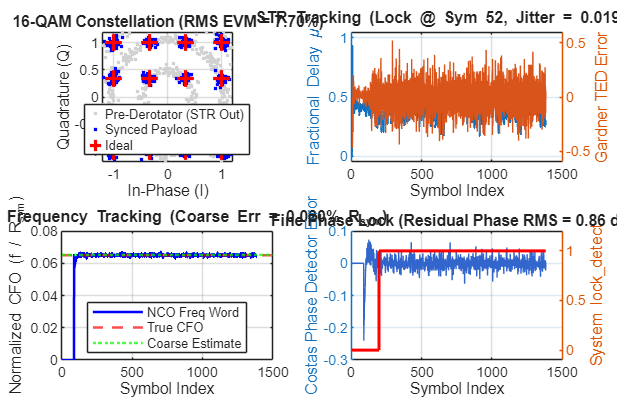

plot_sync_diagnostics(rx_out, metrics, cfg);

## 4. Side-by-Side Comparison: Floating-Point Symbol Model vs. Cycle-Accurate Fixed-Point

modes_cmp = {'float_symbol', 'float_cycle', 'fixed_cycle'};
disp(' ');

disp('=== Architecture Comparison: Symbol-Float vs. Cycle-Float vs. Cycle-Fixed ===');

=== Architecture Comparison: Symbol-Float vs. Cycle-Float vs. Cycle-Fixed ===


for m = 1:numel(modes_cmp)
    cfg_m = cfg;
    cfg_m.exec_mode = modes_cmp{m};
    out_m = run_synchronizer_top(rx_raw, in_valid, cfg_m, []);
    met_m = compute_evm_and_metrics(out_m, payload_syms, cfg_m, meas_esn0);
    disp(sprintf('  Mode: %-14s | RMS EVM = %6.2f%% | SER = %.4f | STR Lock = %3d | Costas Lock = %3d | CFO Err = %.4f%%', ...
        modes_cmp{m}, met_m.evm_rms_pct, met_m.ser, met_m.str_lock_syms, met_m.costas_lock_syms, met_m.coarse_cfo_err_pct));
end

  Mode: float_symbol   | RMS EVM =   7.54% | SER = 0.0000 | STR Lock =  50 | Costas Lock = 193 | CFO Err = 0.0111%


[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt
[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt


  Mode: float_cycle    | RMS EVM =   7.70% | SER = 0.0000 | STR Lock =  52 | Costas Lock = 196 | CFO Err = 0.0199%


[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt
[EXPORT] Hardware parameters successfully exported to: C:\Users\Asem\Desktop\si clash\project code\synchronizer_golden_model\fixed_point_model\config\hw_parameters_exported.txt


  Mode: fixed_cycle    | RMS EVM =   7.70% | SER = 0.0000 | STR Lock =  52 | Costas Lock = 196 | CFO Err = 0.0199%
